# Matlab演習

問1　基本演算と制御文

1から10までの和を計算するスクリプトを以下の4種類作りなさい.

(1)単純に加算（＋）を使う方式

(2)for 文を使う方式

(3)while文を使う方式

(4)関数sumを使う方式

1+2+3+4+5+6+7+8+9+10

ans = 55

s=0;
for x=1:10
    s=s+x;
end
s

s = 55

s3=0;
x3=10;
while x3>=1
    s3=s3+x3;
    x3=x3-1;
end
s3

s3 = 55

問2　グラフの作成

下記の2つの関数をグラフに描画しなさい． 

ヒント：　plotのdocument参照, *x*は*0.1*刻みにする


$$y=\sin \left(2x\right),y=\cos \left(2x\right),x=\left\lbrack -\pi ,\pi \right\rbrack$$


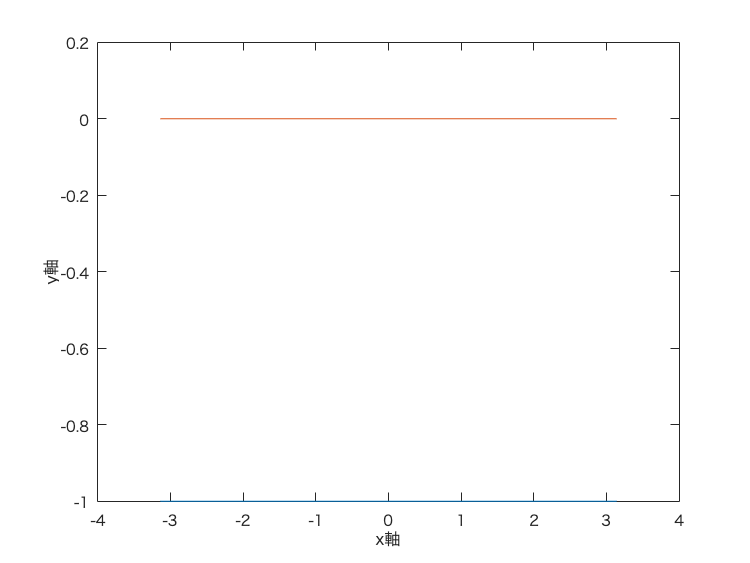

% グラフの初期化
clf
% x の初期化 x=[0:0.1:3*pi]';
% simple plot
x = [-pi,pi];
% y = sin(2*x);
y = cos(2*x);
plot(x, cos(x));
xlabel('x軸');
ylabel('y軸');
hold on;
plot(x, sin(x));

問3　行列の演算

以下の行列をMATLABで定義しなさい.


$$A=\left\lbrack \begin{array}{cc}
2 & 0\\
1 & 3
\end{array}\right\rbrack ,E=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack ,c=\left\lbrack \begin{array}{c}
2\\
6
\end{array}\right\rbrack$$


•定義した行列を使って下記の演算を行いなさい

(1)A＋E  （加算）

(2)AT  （転置行列）

(3)AE  （行列同士の乗算）

(4)Ac  （行列とベクトルの乗算）

(5)3A  （スカラー倍）

(6)x=A\c  （除算　Ax=cとなるxの計算）

(7)Ax  （Ax=c　を数値で確認）

(8)B=A-1  （逆行列を求める）

A = [2 0; 1 3];
E = [1 0; 0 1];
c = [2;6];
A+E

ans =      3     0
     1     4


A.'

ans =      2     1
     0     3


A*E

ans =      2     0
     1     3


A*c

ans =      4
    20


3.*A

ans =      6     0
     3     9


x=A\c

x =     1.0000
    1.6667


c=A*x

c =      2
     6


B = inv(A)

B =     0.5000         0
   -0.1667    0.3333


問4　関数定義と呼び出し

（1）　2次元ベクトル*(x,y)*の長さ*l*を下式で計算する関数length2dを定義しなさい


$$l=\sqrt{x^2 +y^2 }$$


（2）　length2dを使用して次のベクトルの長さを計算しなさい．


$$v=\left(3,4\right)\;\;\;\;\;u=\left(1,1\right)\;$$


v=length2d(3,4)

v = 5

u=length2d(1,1)

u = 1.4142

チャレンジ問題

行列の加算，行列乗算の関数を作成

A=[2 0 1;1 0 3; 0 1 1];
B=[1 0 0;0 1 0; 0 0 1];

C=mat_sum(A,B)

C =      3     0     1
     1     1     3
     0     1     2


C=mat_product(A,B)

C =      2     0     1
     1     0     3
     0     1     1


注意：　使用する関数定義はスクリプトの最後に配置する

ベクトルの長さを計算する関数　length2d

function l=length2d(x,y)
l=sqrt(x^2+y^2);
end

行列加算の関数  mat_sum

function i=mat_sum(x,y)
i=x+y;
end

行列乗算の関数 mat_product

function i=mat_product(x,y)
i=x*y;
end